# **CNN para classificação de batimentos ectópicos **(divisao inter-paciente)

**Divisão inter-paciente**

**Base:** MITBIH_Beats.mat

**Estrutura esperada da base:**

beats    -> 300 x N

labels   -> 1 x N, com 0 = normal e 1 = ectopico

patientId -> 1 x N, identifica o paciente

## 1) Carrega a base

clear; clc;
basePath = 'D:\ProcessamentoDeSinais\TCC\Model\extBati\MITBIH_Beats.mat';
load(basePath);

% As matrizes sao armazenadas em formato de batimentos por coluna.
% Neste arquivo, cada batimento tem 181 amostras e o numero de colunas e N.

beats = double(beats);
labels = double(labels(:).');
patientId = double(patientId(:).');

if size(beats, 2) ~= numel(labels)
    beats = beats.';
end

## **2) Divisao inter-paciente estratificada (80% treino, 10% validacao, 10% teste)**

patientList = unique(patientId);
nPatients = numel(patientList);

patientEctopicCount = zeros(nPatients, 1);
patientBeatCount = zeros(nPatients, 1);
for i = 1:nPatients
    patientMask = patientId == patientList(i);
    patientEctopicCount(i) = sum(labels(patientMask) == 1);
    patientBeatCount(i) = sum(patientMask);
end

rng(42);
tieBreaker = rand(nPatients, 1);
[~, patientOrder] = sortrows([-patientEctopicCount, -patientBeatCount, tieBreaker]);

splitFractions = [0.80, 0.10, 0.10];
targetPatients = max(1, round(splitFractions * nPatients));
targetPatients(1) = nPatients - targetPatients(2) - targetPatients(3);
targetEctopics = splitFractions * sum(patientEctopicCount);

splitOfPatient = zeros(nPatients, 1);
assignedPatients = zeros(1, 3);
assignedEctopics = zeros(1, 3);

for k = 1:nPatients
    patientIndex = patientOrder(k);
    availableSplits = find(assignedPatients < targetPatients);

    % Prioriza o conjunto com maior deficit proporcional de ectopicos.
    ectopicDeficit = (targetEctopics - assignedEctopics) ./ targetEctopics;
    ectopicDeficit(setdiff(1:3, availableSplits)) = -Inf;
    [~, selectedSplit] = max(ectopicDeficit);

    splitOfPatient(patientIndex) = selectedSplit;
    assignedPatients(selectedSplit) = assignedPatients(selectedSplit) + 1;
    assignedEctopics(selectedSplit) = assignedEctopics(selectedSplit) + patientEctopicCount(patientIndex);
end

trainPatients = patientList(splitOfPatient == 1);
valPatients   = patientList(splitOfPatient == 2);
testPatients  = patientList(splitOfPatient == 3);

trainMask = ismember(patientId, trainPatients);
valMask   = ismember(patientId, valPatients);
testMask  = ismember(patientId, testPatients);

% Se houver algum split vazio por causa da distribuicao dos pacientes, corrige
if sum(trainMask) == 0 || sum(valMask) == 0 || sum(testMask) == 0
    error('A divisao inter-paciente gerou algum conjunto vazio. Ajuste a proporcao de pacientes ou verifique os IDs da base.');
end

splitEctopicCounts = [sum(labels(trainMask) == 1), ...
    sum(labels(valMask) == 1), sum(labels(testMask) == 1)];
fprintf('Ectopicos por conjunto: treino=%d, validacao=%d, teste=%d\n', ...
    splitEctopicCounts(1), splitEctopicCounts(2), splitEctopicCounts(3));

Ectopicos por conjunto: treino=17500, validacao=2234, teste=2229



if any(splitEctopicCounts == 0)
    error('A divisao inter-paciente deixou algum conjunto sem ectopicos. Ajuste a base ou as proporcoes.');
end

## **3) Monta os tensores de entrada**

Xtrain = reshape(beats(:, trainMask), [300, 1, 1, sum(trainMask)]);
Xval   = reshape(beats(:, valMask),   [300, 1, 1, sum(valMask)]);
Xtest  = reshape(beats(:, testMask),  [300, 1, 1, sum(testMask)]);

Ytrain = categorical(labels(trainMask), [0 1], {'Normal', 'Ectopic'});
Yval   = categorical(labels(valMask),   [0 1], {'Normal', 'Ectopic'});
Ytest  = categorical(labels(testMask),  [0 1], {'Normal', 'Ectopic'});
classNames = categories(Ytrain);

## **4). Arquitetura CNN 1D **

layers = [

    imageInputLayer([300 1 1], ...
        'Name', 'input', ...
        'Normalization', 'none')

    convolution2dLayer([5 1], 64, ...
        'Padding', 'same', ...
        'Name', 'conv1')
    reluLayer('Name', 'relu1')

    convolution2dLayer([5 1], 64, ...
        'Padding', 'same', ...
        'Name', 'conv2')
    reluLayer('Name', 'relu2')
    
    dropoutLayer(0.3, 'Name', 'drop_conv2')
    maxPooling2dLayer([2 1], ...
        'Stride', [2 1], ...
        'Name', 'pool1')

    convolution2dLayer([3 1], 128, ...
        'Padding', 'same', ...
        'Name', 'conv3')
    reluLayer('Name', 'relu3')

    convolution2dLayer([3 1], 128, ...
        'Padding', 'same', ...
        'Name', 'conv4')
    reluLayer('Name', 'relu4')
    
    dropoutLayer(0.3, 'Name', 'drop_conv4')
    maxPooling2dLayer([2 1], ...
        'Stride', [2 1], ...
        'Name', 'pool2')

    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    dropoutLayer(0.3, 'Name', 'drop_fc1')

    fullyConnectedLayer(128, 'Name', 'fc2')
    reluLayer('Name', 'relu_fc2')
    dropoutLayer(0.3, 'Name', 'drop_fc2')

    fullyConnectedLayer(2, 'Name', 'fc3')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOut', ...
        'Classes', classNames)
];


### 5) Plot da arquitetura

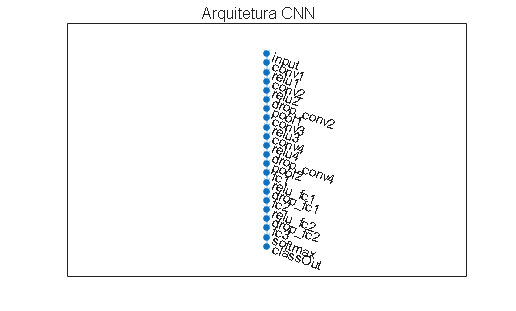

deepNetworkDesigner(layers);
lgraph = layerGraph(layers);

figure;
plot(lgraph) 
sgtitle('Arquitetura CNN');

## **6) Opcoes de treinamento**


options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 256, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {Xval, Yval}, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

## 7) Treinamento

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       34.77% |       77.82% |       0.6976 |       0.6659 |          0.0010 |
|       1 |          30 |       00:00:50 |       91.80% |       94.34% |       0.2362 |       0.1649 |          0.0010 |
|       1 |          50 |       00:01:10 |       90.62% |              |       0.2143 |              |          0.0010 |
|       1 |          60 |       00:01:29 |       95.31% |       93.98% |       0.1542 |       0.1532 |          0.0010 |
|       

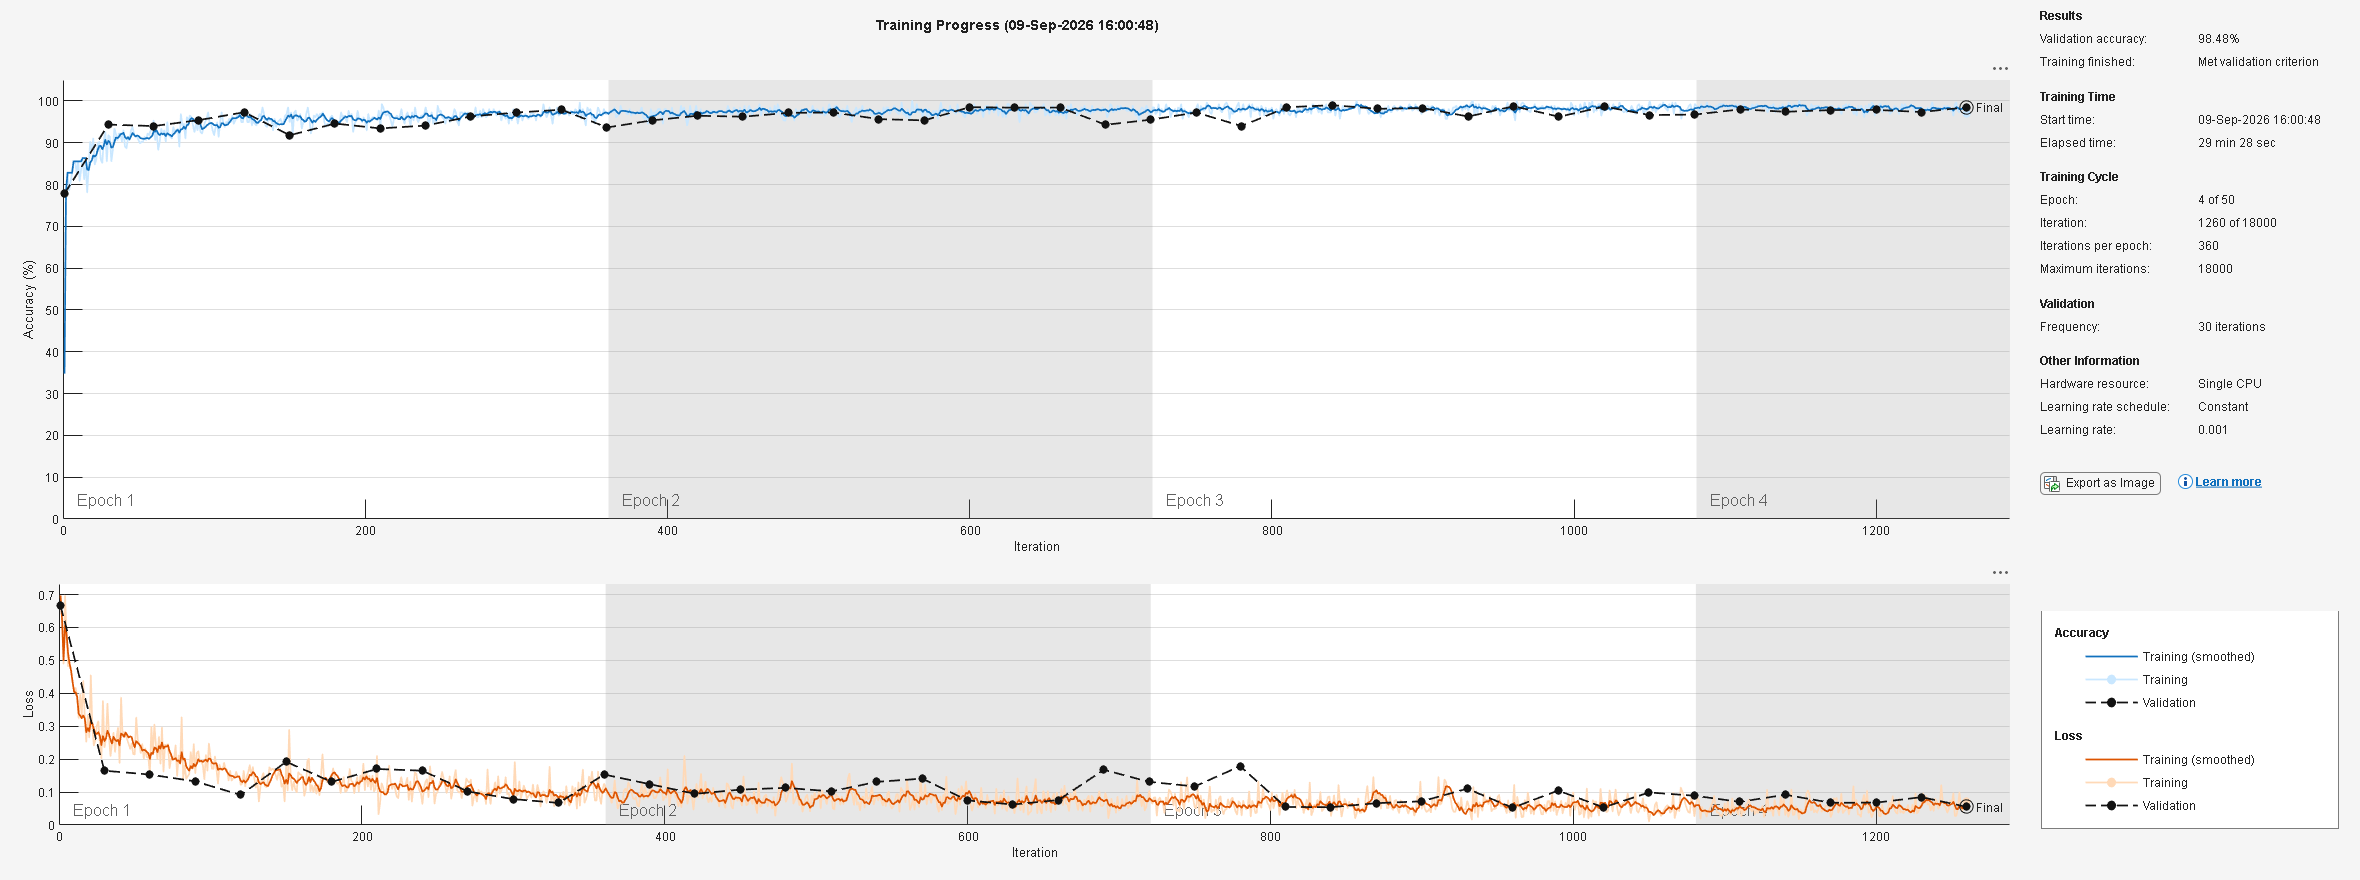

% Fixa a inicializacao da rede para comparacoes reproduziveis.
rng(42);
net = trainNetwork(Xtrain, Ytrain, layers, options);

## Salva a rede

modelPath = fullfile(fileparts(mfilename('fullpath')), ...
    'CNN_Ectopic_InterPatient.mat');
windowBefore = 150;
windowAfter = 149;
inputLength = windowBefore + windowAfter + 1;
save(modelPath, 'net', 'classNames', 'optimalThreshold', ...
    'windowBefore', 'windowAfter', 'inputLength');
fprintf('Modelo salvo em: %s\n', modelPath);

## 8) Avaliaçao do modelo no conjunto de teste


% Seleciona o limiar da classe Ectopic exclusivamente na validacao,
% maximizando o F1-score. Em caso de empate, usa o valor mais proximo de 0.5.
[~, scoresVal] = classify(net, Xval);
ectopicIdx = find(strcmp(classNames, 'Ectopic'), 1);
thresholds = (0:0.01:1).';
f1Val = zeros(numel(thresholds), 1);
isEctopicVal = Yval(:) == 'Ectopic';

for i = 1:numel(thresholds)
    predEctopicVal = scoresVal(:, ectopicIdx) >= thresholds(i);
    tp = sum(predEctopicVal & isEctopicVal);
    fp = sum(predEctopicVal & ~isEctopicVal);
    fn = sum(~predEctopicVal & isEctopicVal);

    if (2 * tp + fp + fn) > 0
        f1Val(i) = (2 * tp) / (2 * tp + fp + fn);
    end
end

bestF1Val = max(f1Val);
candidateIdx = find(abs(f1Val - bestF1Val) < eps);
[~, nearestToHalf] = min(abs(thresholds(candidateIdx) - 0.5));
bestIdx = candidateIdx(nearestToHalf);
optimalThreshold = thresholds(bestIdx);

% Aplica no teste somente o limiar definido acima.
[~, scoresTest] = classify(net, Xtest);
YPred = categorical(repmat({'Normal'}, numel(Ytest), 1), classNames);
YPred(scoresTest(:, ectopicIdx) >= optimalThreshold) = 'Ectopic';

% Acuracia global
acc = mean(YPred(:) == Ytest(:));

% Classes existentes
classes = categories(Ytest);
numClasses = numel(classes);

% Matriz de confusao
cm = confusionmat(Ytest, YPred, ...
    'Order', categorical(classes));

fprintf('\n============================================\n');

fprintf('        AVALIACAO NO CONJUNTO DE TESTE\n');

        AVALIACAO NO CONJUNTO DE TESTE


fprintf('============================================\n');


fprintf('Acuracia: %.4f (%.2f%%)\n', acc, acc*100);

Acuracia: 0.9843 (98.43%)


fprintf('Limiar otimo para Ectopic na validacao: %.2f (F1 = %.4f)\n', ...
    optimalThreshold, bestF1Val);

Limiar otimo para Ectopic na validacao: 0.58 (F1 = 0.9672)



%% Calculo das metricas por classe

precision   = zeros(numClasses,1);
sensitivity = zeros(numClasses,1);
specificity = zeros(numClasses,1);
f1score     = zeros(numClasses,1);

totalSamples = sum(cm(:));

for i = 1:numClasses

    % Verdadeiros positivos
    TP = cm(i,i);

    % Falsos positivos
    FP = sum(cm(:,i)) - TP;

    % Falsos negativos
    FN = sum(cm(i,:)) - TP;

    % Verdadeiros negativos
    TN = totalSamples - TP - FP - FN;

    % Precisao / PPV
    if (TP + FP) > 0
        precision(i) = TP / (TP + FP);
    else
        precision(i) = 0;
    end

    % Sensibilidade / Recall
    if (TP + FN) > 0
        sensitivity(i) = TP / (TP + FN);
    else
        sensitivity(i) = 0;
    end

    % Especificidade
    if (TN + FP) > 0
        specificity(i) = TN / (TN + FP);
    else
        specificity(i) = 0;
    end

    % F1-score
    if (precision(i) + sensitivity(i)) > 0
        f1score(i) = 2 * ...
            (precision(i) * sensitivity(i)) / ...
            (precision(i) + sensitivity(i));
    else
        f1score(i) = 0;
    end
end

%% Tabela de resultados por classe

metricas = table( ...
    categorical(classes), ...
    precision, ...
    sensitivity, ...
    specificity, ...
    f1score, ...
    'VariableNames', { ...
    'Classe', ...
    'Precisao', ...
    'Sensibilidade', ...
    'Especificidade', ...
    'F1_Score'});

disp(' ');

disp('Metricas por classe:');

Metricas por classe:


disp(metricas);

    Classe     Precisao    Sensibilidade    Especificidade    F1_Score
    _______    ________    _____________    ______________    ________

    Normal     0.99669        0.98318          0.98834        0.98989 
    Ectopic    0.94266        0.98834          0.98318        0.96496 




%% Metricas macro

precisionMacro   = mean(precision);
sensitivityMacro = mean(sensitivity);
specificityMacro = mean(specificity);
f1Macro          = mean(f1score);

fprintf('\n--------------------------------------------\n');


--------------------------------------------


fprintf('Metricas macro:\n');

Metricas macro:


fprintf('Precisao macro:       %.4f (%.2f%%)\n', ...
    precisionMacro, precisionMacro*100);

Precisao macro:       0.9697 (96.97%)



fprintf('Sensibilidade macro:  %.4f (%.2f%%)\n', ...
    sensitivityMacro, sensitivityMacro*100);

Sensibilidade macro:  0.9858 (98.58%)



fprintf('Especificidade macro: %.4f (%.2f%%)\n', ...
    specificityMacro, specificityMacro*100);

Especificidade macro: 0.9858 (98.58%)



fprintf('F1-score macro:       %.4f (%.2f%%)\n', ...
    f1Macro, f1Macro*100);

F1-score macro:       0.9774 (97.74%)


--------------------------------------------


###  9) Matriz de confusão

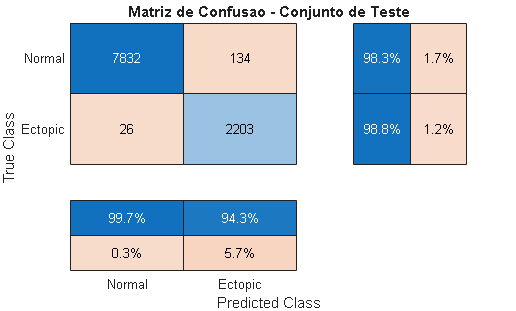


figure;

confusionchart(Ytest, YPred, ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');

title('Matriz de Confusao - Conjunto de Teste');

### 10) Matriz de confusao normalizada

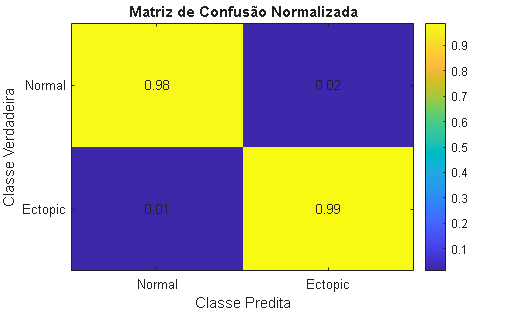


cmNormalized = cm ./ sum(cm, 2);

% Evita NaN caso alguma classe nao possua amostras
cmNormalized(isnan(cmNormalized)) = 0;

figure;

imagesc(cmNormalized);
colorbar;

title('Matriz de Confusão Normalizada');
xlabel('Classe Predita');
ylabel('Classe Verdadeira');

xticks(1:numClasses);
yticks(1:numClasses);

xticklabels(classes);
yticklabels(classes);

% Mostrar os valores dentro da matriz
for i = 1:numClasses
    for j = 1:numClasses
        text(j, i, sprintf('%.2f', cmNormalized(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle');
    end
end

## 12) Visualização de algumas predições

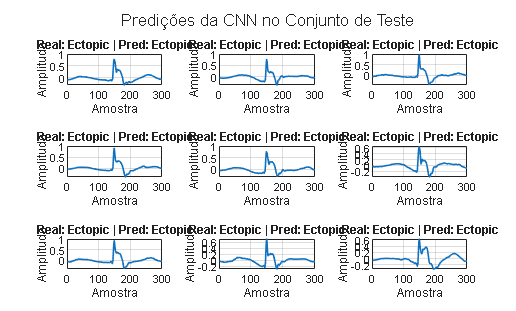


numSamplesPlot = min(9, numel(Ytest));

figure;

tiledlayout(3,3);

for i = 1:numSamplesPlot

    nexttile;

    % Extrai a primeira amostra
    signal = squeeze(Xtest(:,1,1,i));

    plot(signal, 'LineWidth', 1.2);
    grid on;

    title(sprintf( ...
        'Real: %s | Pred: %s', ...
        string(Ytest(i)), ...
        string(YPred(i))));

    xlabel('Amostra');
    ylabel('Amplitude');

end

sgtitle('Predições da CNN no Conjunto de Teste');

## 13) Resultado da primeira amostra

fprintf('Primeira amostra do conjunto de teste:\n');

Primeira amostra do conjunto de teste:


fprintf('Classe verdadeira: %s\n', string(Ytest(1)));

Classe verdadeira: Ectopic


fprintf('Classe prevista:   %s\n', string(YPred(1)));

Classe prevista:   Ectopic
